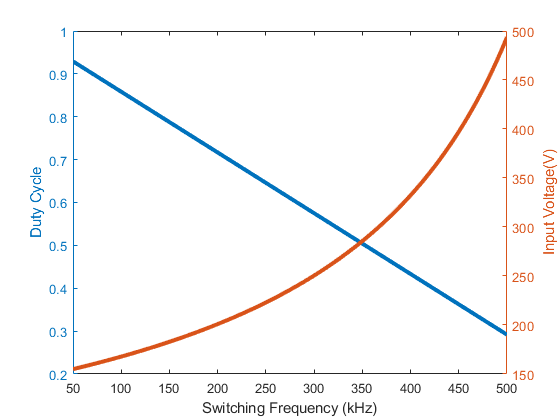

Rload = 24; %ohms
Iout = 6; %A
Pout = Iout^2*Rload;
Vout = Iout*Rload;
DeltaI = 30;
IndMaxPeak = (Iout + DeltaI)/2;
IndMinPeak = (Iout - DeltaI)/2;
fsw = 50e3:5e3:500e3;
L = 6.8e-6;
D = 1 - L.*fsw*DeltaI/Vout;
Vin = Vout./D;
figure
yyaxis left
plot(fsw/1e3,D, 'LineWidth', 3);
ylabel('Duty Cycle')
yyaxis right
plot(fsw/1e3,Vin,'LineWidth', 3);
xlabel('Switching Frequency (kHz)')
ylabel('Input Voltage (V)')